# Assessing bias and variance in mixed effects model estimates using simulation

### Specify input parameters

n_i = 20;           % len
m = 5;              % sub
p = 2;              % num params
b_g = [1 3]';       % fixed effects: Intercept and slope    
s2 = 25;            % residual var
U_g = [2 0; 0 4];   % Cov matrix of random intercept and slope
regressortype = 'continuous';

% These are params whose estimates we will compare later in the report
fixedint = b_g(1);
fixedslope = b_g(2); 
 
withinerr_std = sqrt(s2);

randintvar = U_g(1, 1);
randslopevar = U_g(2, 2);
 

### **Test run**

Generate a dataset, fit the model, and plot the results

MST (diag of Ystar_mtx): 24.81346
MSE (diag of resid): -0.93516


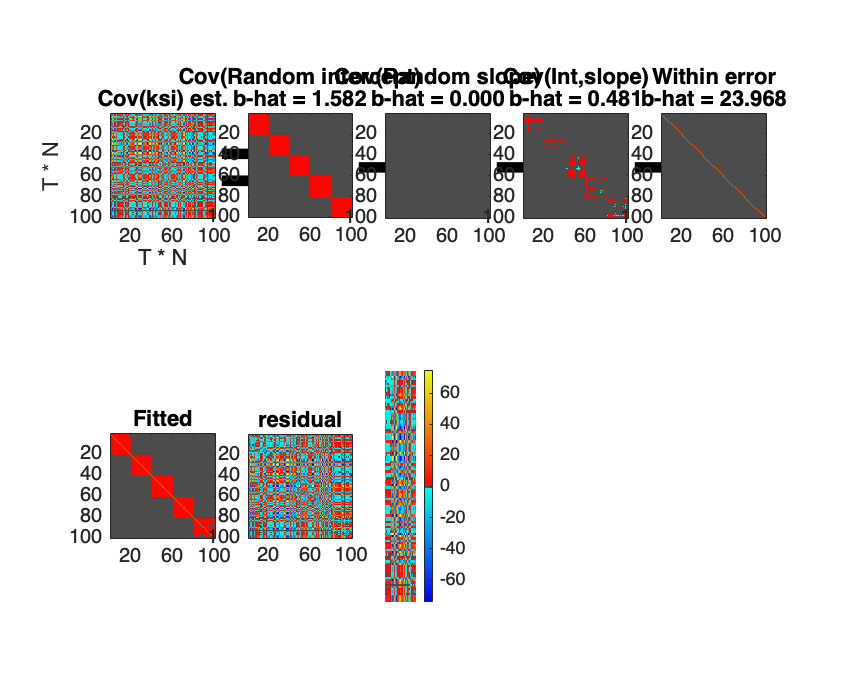

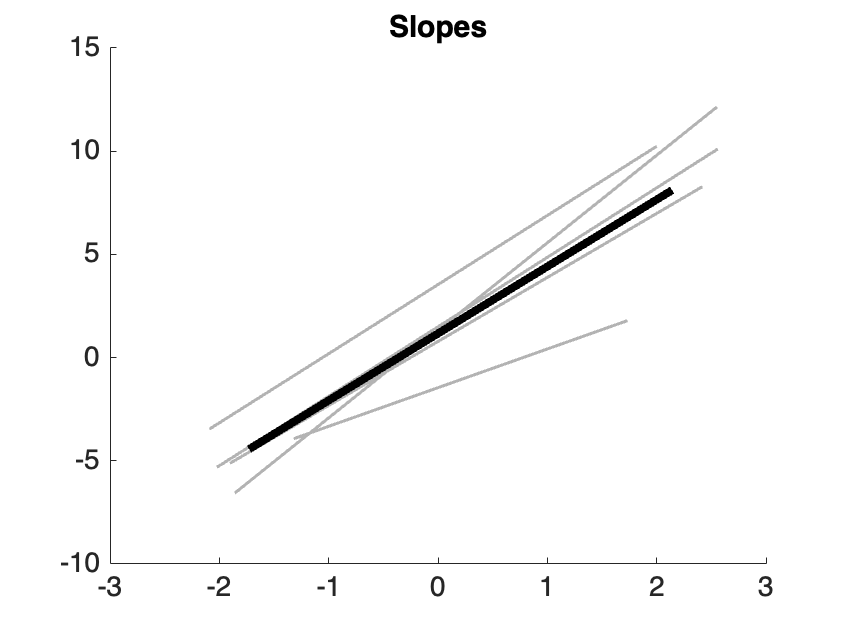


igls.m output report:
---------------------------------------
Data:  20 observations x   5 subjects 
Fit Type: igls
AR(p) model: No
Converged: Yes
Max iterations:   5, Completed iterations:   1
Epsilon for convergence: 0.010000
Elapsed time: 0.22 s

Statistics: Tests of inference on fixed population parameters
Parameter	est.	t(  4)	p	
Intcpt.	1.168	1.55	0.195429	 
Slope1	3.243	6.40	0.003068	**


Statistics: Tests of significance on random effects (variances)
Parameter	est.	LRT	p	
Intcpt.	1.582	3.33	0.083327	+
Slope1	0.000	0.54	0.782404	 

---------------------------------------



[y, Z_i, x, sim_data] = sim_generate_mixedfx_data1(m, n_i, p, b_g, s2, U_g, regressortype);

out = igls(y, x, 'plot', 'all');

### Run simulation


iter = 500;

[fixedfx_hat, rfx_hat] = deal(zeros(2, iter));
s2_within = zeros(1, iter);

tic
for iteration = 1:iter

    % Generate data
    [y, Z_i, x, sim_data] = sim_generate_mixedfx_data1(m, n_i, p, b_g, s2, U_g, regressortype);

    % Fit model
    out = igls(y, x, 'noverbose');  % for igls

    % Save estimates to check
    fixedfx_hat(:, iteration) = out.beta;

    rfx_hat(:, iteration) = out.betastar;

    s2_within(:, iteration) = out.Sigma;

    if mod(iteration, 100) == 0
        toc
    end

end

Elapsed time is 19.303121 seconds.
Elapsed time is 38.407201 seconds.
Elapsed time is 57.610931 seconds.
Elapsed time is 76.902973 seconds.
Elapsed time is 96.060025 seconds.


toc

Elapsed time is 96.167531 seconds.


### Print a report of the output: Bias and variance of estimates

% Calculate means, bias (deviations), and variances for estimates across
% iterations

fixedfxmean = mean(fixedfx_hat, 2);
rfxmean = mean(rfx_hat, 2);
s2mean = mean(s2_within, 2);

fixedfxbias = [fixedint; fixedslope] - fixedfxmean;
rfxbias = [randintvar; randslopevar] - rfxmean;
s2bias = withinerr_std .^ 2 - s2mean;

% Significance test for estimation bias
% Does the model produce the true values on average?
% A significant P-value here indicates systematic bias, which is bad for the model.

devs = (fixedfx_hat - [fixedint; fixedslope])'; % iteration-by-iteration deviations
[~, fixedfx_bias_p, ~, fixedfx_bias_stats] = ttest(devs);

devs = (rfx_hat - [randintvar; randslopevar])'; % iteration-by-iteration deviations
[~, rfx_bias_p, ~, rfx_bias_stats] = ttest(devs);

devs = (withinerr_std .^ 2 - s2_within)'; % iteration-by-iteration deviations
[~, s2_bias_p, ~, s2_bias_stats] = ttest(devs);

% Variance of estimates across iterations
% Lower is better

fixedfx_err_var = var(fixedfx_hat, 0, 2);
rfx_err_var = var(rfx_hat, 0, 2);
s2_err_var = var(s2_within, 0, 2);

% Print output
uline = '_______________________________________________________________';
disp(uline)

_______________________________________________________________


disp('Bias and variance of model estimates compared with ground truth')

Bias and variance of model estimates compared with ground truth


disp(uline)

_______________________________________________________________



t = table([fixedint; fixedslope], fixedfxmean, fixedfx_bias_stats.tstat', fixedfx_bias_p', fixedfx_err_var, 'VariableNames', {'Truth' 'Mean Est.' 'Bias t-stat' 'Bias p-val' 'Var of Est.'}, 'RowNames', {'Intercept' 'Slope'});
disp('Fixed effects'); disp(t);

Fixed effects
                 Truth    Mean Est.    Bias t-stat    Bias p-val    Var of Est.
                 _____    _________    ___________    __________    ___________

    Intercept      1       0.99856      -0.035953       0.97133       0.80097  
    Slope          3        2.8867        -2.0865      0.037438         1.475  




t = table([randintvar; randslopevar], rfxmean, rfx_bias_stats.tstat', rfx_bias_p', rfx_err_var, 'VariableNames', {'Truth' 'Mean Est.' 'Bias t-stat' 'Bias p-val' 'Var of Est.'}, 'RowNames', {'Intercept' 'Slope'});
disp('Random effects'); disp(t);

Random effects
                 Truth    Mean Est.    Bias t-stat    Bias p-val    Var of Est.
                 _____    _________    ___________    __________    ___________

    Intercept      2       1.4832         -5.652      2.6711e-08      4.1807   
    Slope          4        2.921        -6.6518       7.624e-11      13.157   




t = table(withinerr_std .^ 2, s2mean, s2_bias_stats.tstat', s2_bias_p', s2_err_var, 'VariableNames', {'Truth' 'Mean Est.' 'Bias t-stat' 'Bias p-val' 'Var of Est.'}, 'RowNames', {'Error Sigma^2'});
disp('Residual variance'); disp(t);

Residual variance
                     Truth    Mean Est.    Bias t-stat    Bias p-val    Var of Est.
                     _____    _________    ___________    __________    ___________

    Error Sigma^2     25       25.227        -1.3878        0.1658        13.403   

